clear ; close all ; clc

syms s

% gamma = [-10 -5 -3 -1 0 0.25 0.5 0.75 1 1.4485 2]';
gamma = [-2:1:0 0.25:0.25:2]';
full_gain = gamma + -1;
% gamma = 0;
n_gamma = length(gamma);

tau = 0.155;
G = tf(2.23, [tau 1]);
% G.IOdelay = 0.02;
G = pade(G, 1)

G =
 
     2.23
  -----------
  0.155 s + 1
 
Continuous-time transfer function.



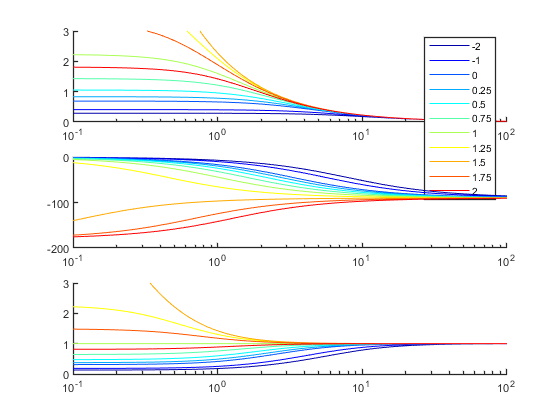

% H = minreal(G / (1 - G*(-1 + gamma)))
% fv = (0.01:100)';
fv = logspace(-1,2, 1000)';
wv = fv*2*pi;
nf = length(fv);
Gain = nan(nf, n_gamma);
Phase = nan(nf, n_gamma);
Error = nan(nf, n_gamma);
for n = 1:n_gamma
    H(n).main = minreal(G / (1 - G*(-1 + gamma(n))));
    [gain,phase] = bode(H(n).main, wv);
    Gain(:,n) = squeeze(gain);
    Phase(:,n) = squeeze(phase);
    
    E(n).main = minreal(1 + H(n).main*(-1 + gamma(n)));
    [gain,~] = bode(E(n).main, wv);
    EGain(:,n) = squeeze(gain);
end

fig = figure (1); clf
set(fig, 'Color', 'w')
ax(1) = subplot(3,1,1); cla ; hold on ; ylim([0 3])
    h.gain = plot(fv, Gain);

ax(2) = subplot(3,1,2); cla ; hold on ; %ylim([-90 20])
    h.phase = plot(fv, Phase - 0*360);
    
ax(3) = subplot(3,1,3); cla ; hold on ; ylim([0 3])
    h.error = plot(fv, EGain);
    
legend(h.gain, string(gamma))

set(ax, 'Color', 'none', 'LineWidth', 1, 'XScale', 'log')

cc = jet(n_gamma);
set(h.gain, {'Color'}, num2cell(cc,2))
set(h.phase, {'Color'}, num2cell(cc,2))
set(h.error, {'Color'}, num2cell(cc,2))

clear ; close all ; clc
syms s K_p tau gamma

P = 1 / (tau*s + 1);
C = K_p;
G = P*C

$$G = \frac{K_{p}}{s\,\tau +1}$$

H = G / (1 - G*(-1 + gamma));
H = collect(H,s)

$$H = \frac{K_{p}}{K_{p}-K_{p}\,\gamma +s\,\tau +1}$$


[N,D] = numden(H)

$$N = K_{p}$$

$$D = K_{p}-K_{p}\,\gamma +s\,\tau +1$$


char_eq = D == 0

$$char\_eq = K_{p}-K_{p}\,\gamma +s\,\tau +1=0$$

solve(char_eq, s)

$$ans = -\frac{K_{p}-K_{p}\,\gamma +1}{\tau }$$